Declaration of variables

clc;
clear;

Road_length = 100;
car_number   = 10

car_number = 10

acceleration =4.5

acceleration = 4.5000

deceleration =-3.5

deceleration = -3.5000

%initial speed
u = 5

u = 5

%time limitis
time =100

time = 100

%limit speed
lim = 15

lim = 15

%initial position of car
J = 1:car_number

J =      1     2     3     4     5     6     7     8     9    10


A = rand(1,car_number).*Road_length

A =    81.4724   90.5792   12.6987   91.3376   63.2359    9.7540   27.8498   54.6882   95.7507   96.4889


x(J,1)= sort(A)

x =     9.7540
   12.6987
   27.8498
   54.6882
   63.2359
   81.4724
   90.5792
   91.3376
   95.7507
   96.4889


v(J,1)=randi([0,10],10,1)

v =      1
    10
    10
     5
     8
     1
     4
    10
     8
    10


%minimum distance between cars
x0 = Road_length/car_number

x0 = 10

num = car_number-1

num = 9

delT=0.1

delT = 0.1000

k = time / delT

k = 1000

initialize road

for T=2:k
    for J=1:car_number
        if J == car_number
            dis(J,T) = x(1,T-1)-x(J,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > x0
           v(J,T)=v(J,T-1) + acceleration;
        elseif dis(J,T) <= deceleration
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        x(J,T)=x(J,T-1)+v(J,T)*delT;
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
end
x(J,T)=x(J,T)

x =     9.7540    9.7540    9.7540    9.7540    9.7540    9.7540   10.2040   11.1040   12.4540   13.9540   15.4540   16.9540   18.4540   19.9540   21.4540   22.9540   24.4540   25.9540   27.4540   28.9540   30.4540   31.9540   33.4540   34.9540   36.4540   37.9540   39.4540   40.9540   42.4540   43.9540   45.4540   46.6040   47.4040   47.8540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   47.9540   48.4040
   12.6987   14.1487   15.6487   17.1487   18.6487   20.1487   21.6487   23.1487   24.6487   26.1487   27.6487   29.1487   30.6487   32.1487   33.6487   35.1487   36.6487   38.1487   39.6487   41.1487   42.6487   44.1487   45.6487   47.1487   48.6487   50.1487   51.6487   52.7987   53.5987   54.0487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.1487   54.5987   55.4987   56.8487   58.3487   59

v(J,T)=v(J,T)

v =     1.0000         0         0         0         0         0    4.5000    9.0000   13.5000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   11.5000    8.0000    4.5000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0    4.5000
   10.0000   14.5000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   11.5000    8.0000    4.5000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0    4.5000    9.0000   13.5000   15.0000   15

Plot

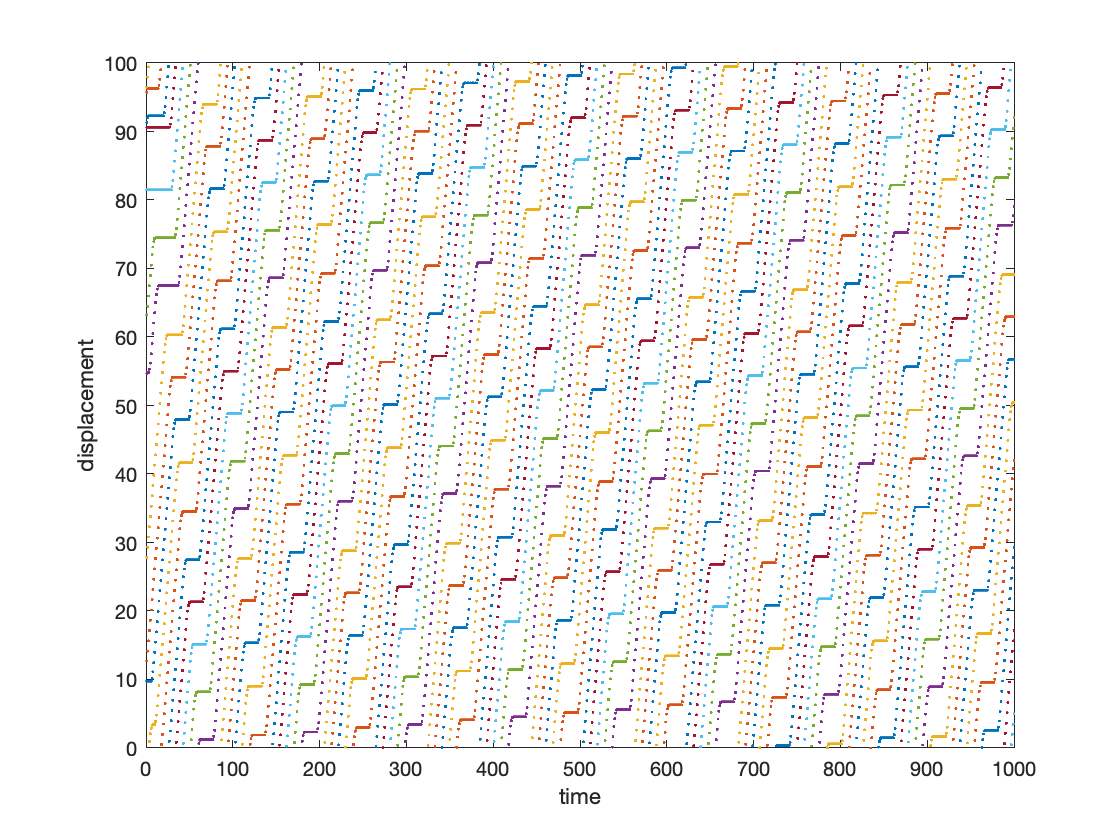

plot(x(1,:),".","MarkerSize",1);
hold on
for b = 2: car_number
    plot(x(b,:),".","MarkerSize",1)
end
xlabel('time')
ylabel('displacement')
hold off;